simout = Get_Sim_Output(out)

simout = struct with fields:
     time: [275×1 double]
        x: [275×6 double]
    utraj: [50×2×89 double]
    xtraj: [50×6×89 double]


dtime = 0.3;

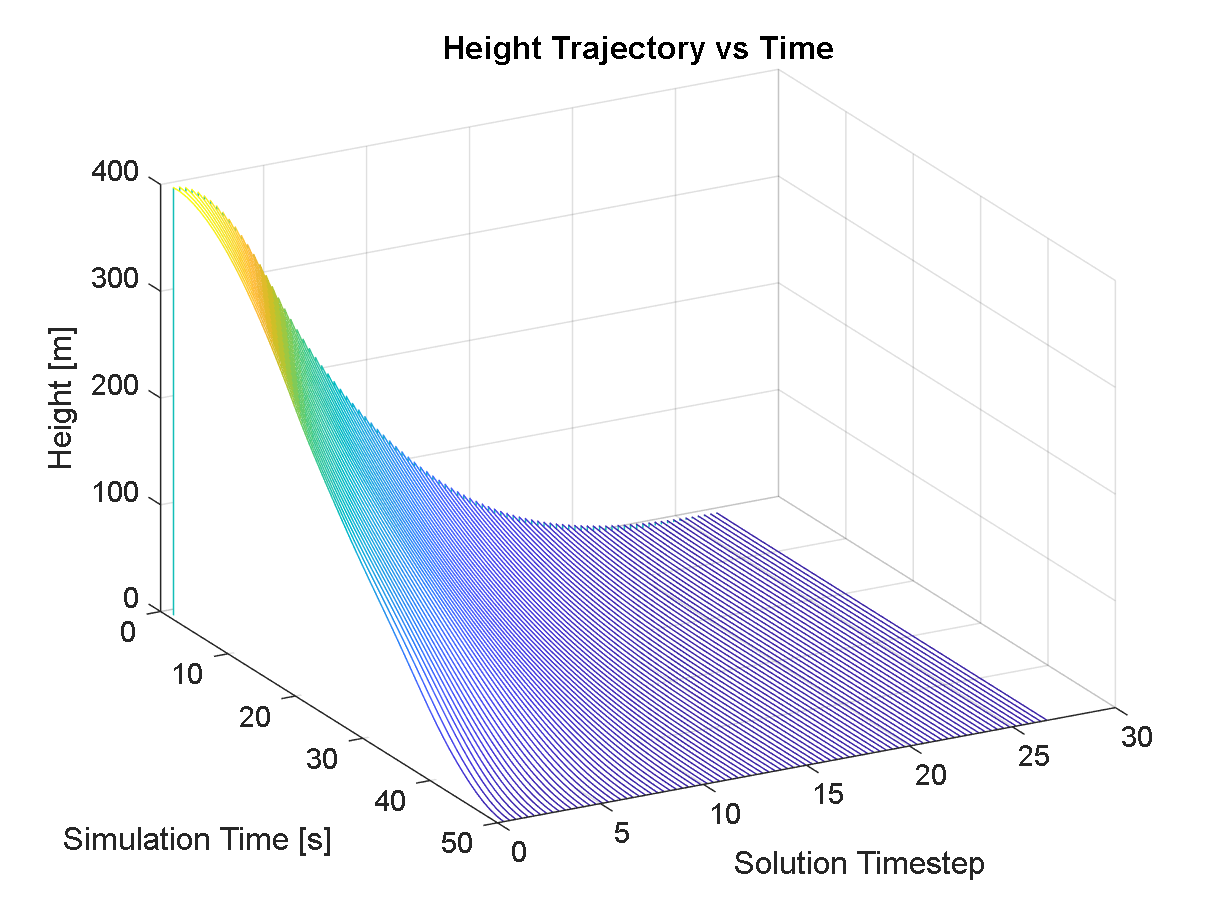

Z = squeeze(simout.xtraj(:,2,:));
[X, Y] = meshgrid(1:size(simout.utraj, 1),(1:size(simout.utraj, 3))/size(simout.utraj, 3) * max(simout.time));
waterfall(X, Y, Z');
xlabel("Simulation Time [s]")
ylabel("Solution Timestep")
zlabel("Height [m]")
title("Height Trajectory vs Time")

view([61.4 29.4])

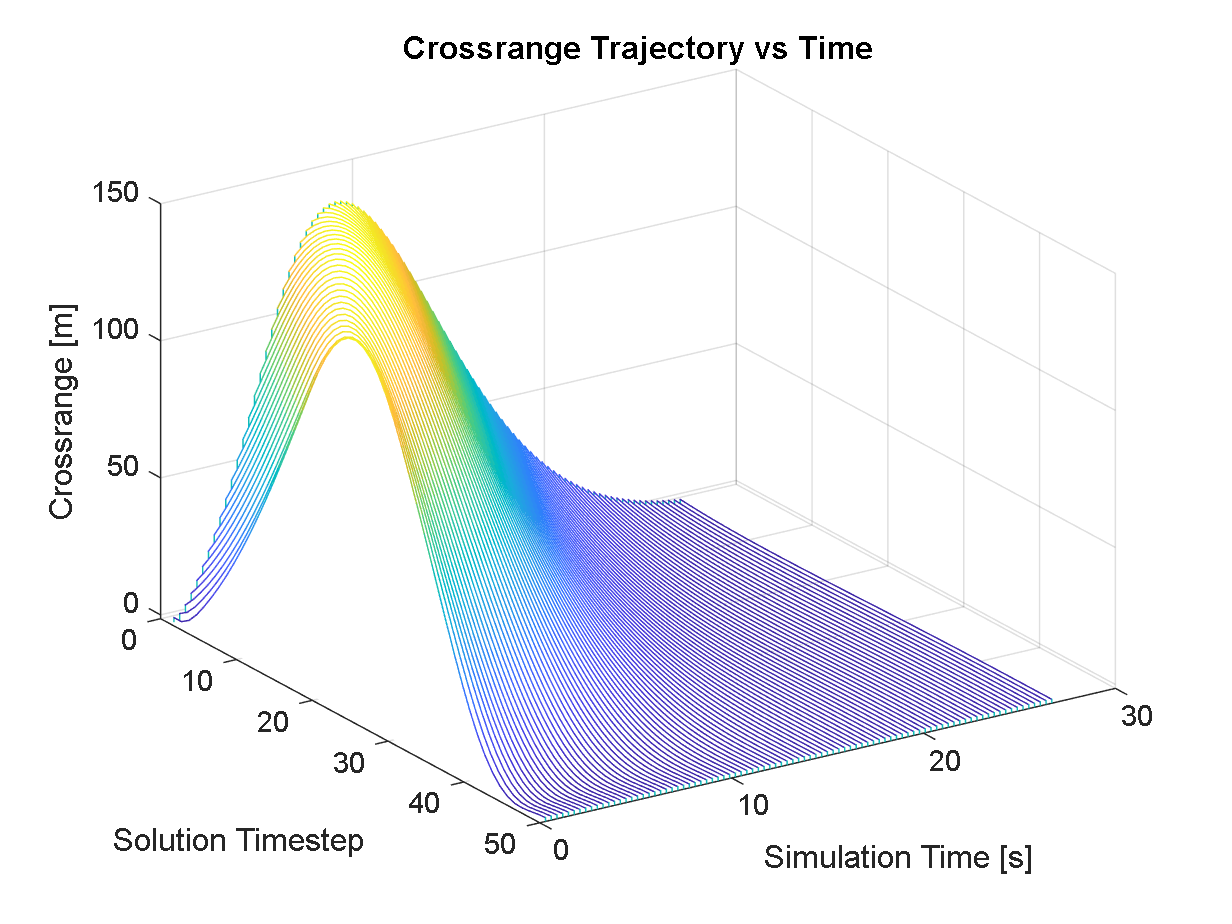

Z = squeeze(simout.xtraj(:,1,:));
[X, Y] = meshgrid(1:size(simout.utraj, 1),(1:size(simout.utraj, 3))/size(simout.utraj, 3) * max(simout.time));
waterfall(X, Y, Z');
ylabel("Simulation Time [s]")
xlabel("Solution Timestep")
zlabel("Crossrange [m]")
title("Crossrange Trajectory vs Time")

view([61.4 29.4])

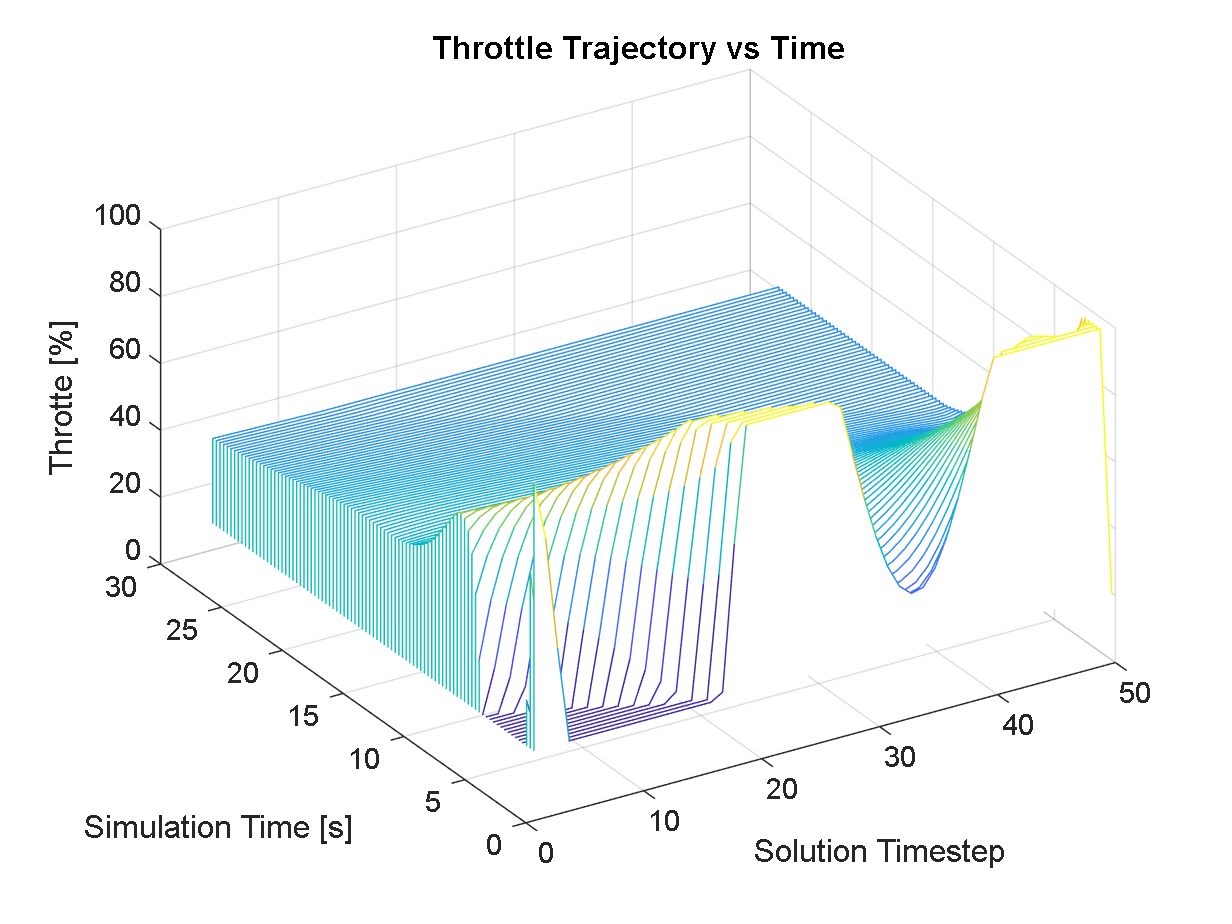

Z = squeeze(simout.utraj(:,1,:));
waterfall(X, Y, Z' * 100);
ylabel("Simulation Time [s]")
xlabel("Solution Timestep")
zlabel("Throtte [%]")
title("Throttle Trajectory vs Time")

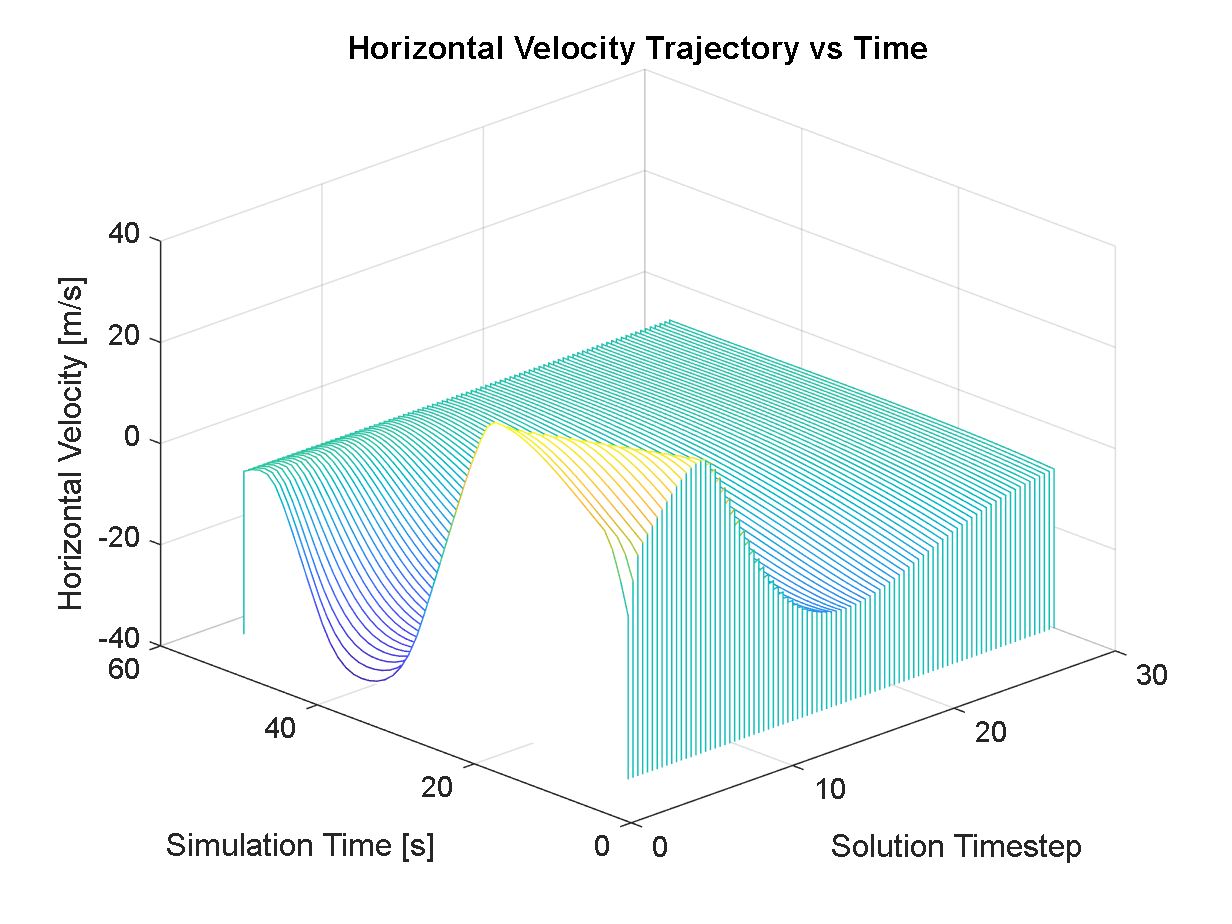

Z = squeeze(simout.xtraj(:,3,:));
waterfall(Y, X, Z');
ylabel("Simulation Time [s]")
xlabel("Solution Timestep")
zlabel("Horizontal Velocity [m/s]")
title("Horizontal Velocity Trajectory vs Time")

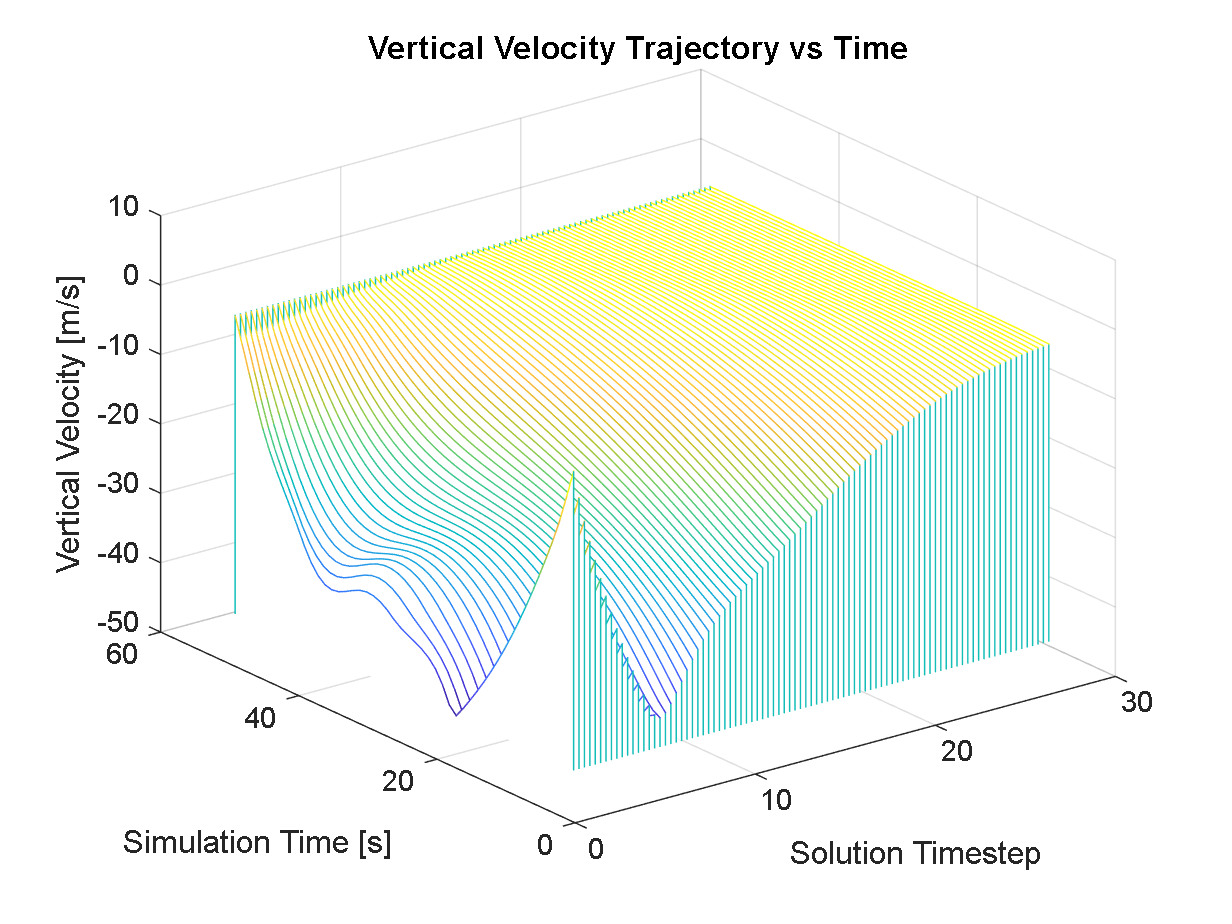

Z = squeeze(simout.xtraj(:,4,:));
waterfall(Y, X, Z');
ylabel("Simulation Time [s]")
xlabel("Solution Timestep")
zlabel("Vertical Velocity [m/s]")
title("Vertical Velocity Trajectory vs Time")

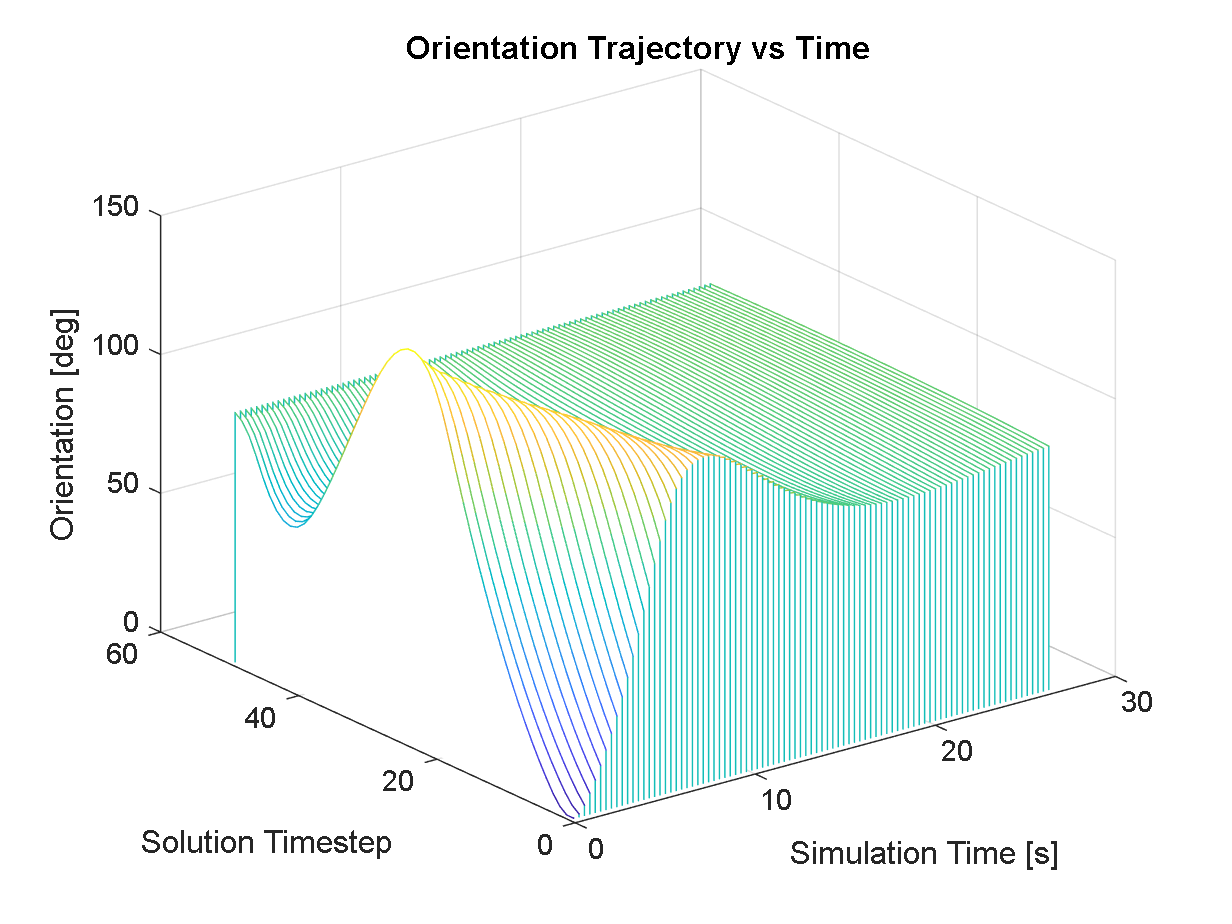

Z = squeeze(rad2deg(simout.xtraj(:,5,:)));
waterfall(Y, X, Z');
xlabel("Simulation Time [s]")
ylabel("Solution Timestep")
zlabel("Orientation [deg]")
title("Orientation Trajectory vs Time")

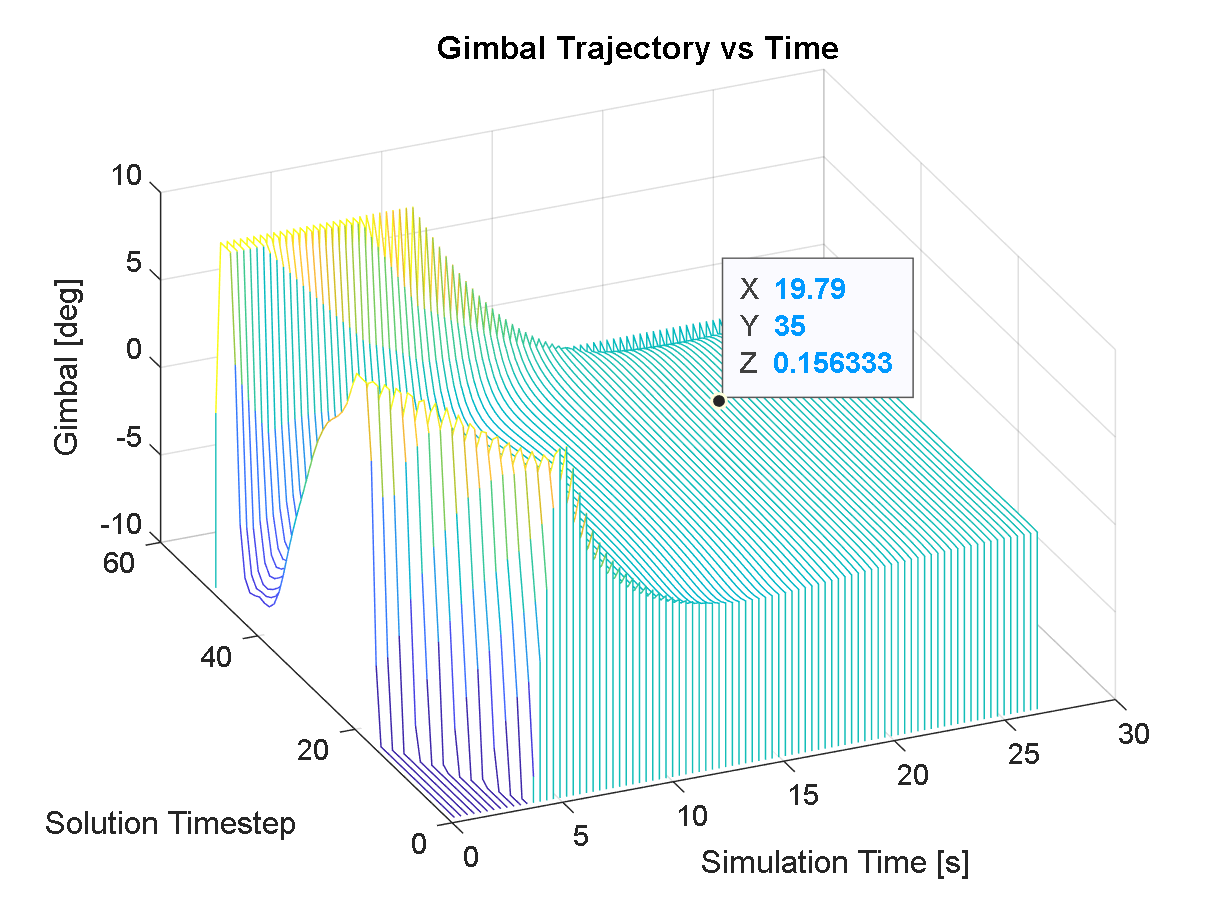

Z = squeeze(rad2deg(simout.utraj(:,2,:)));
waterfall(Y, X, Z');
xlabel("Simulation Time [s]")
ylabel("Solution Timestep")
zlabel("Gimbal [deg]")
title("Gimbal Trajectory vs Time")